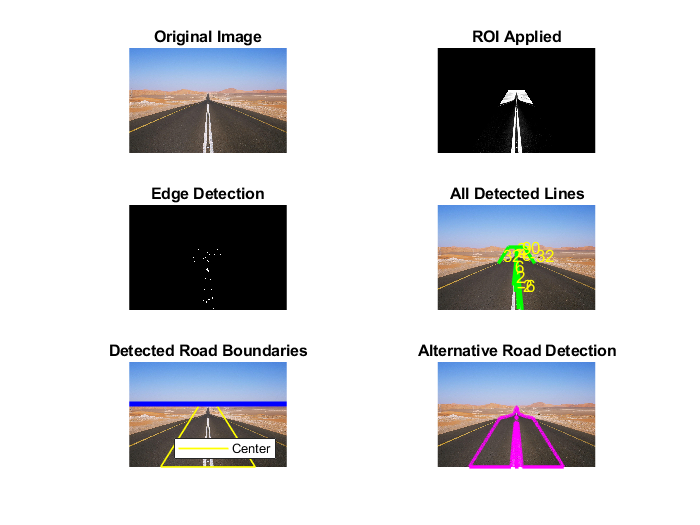

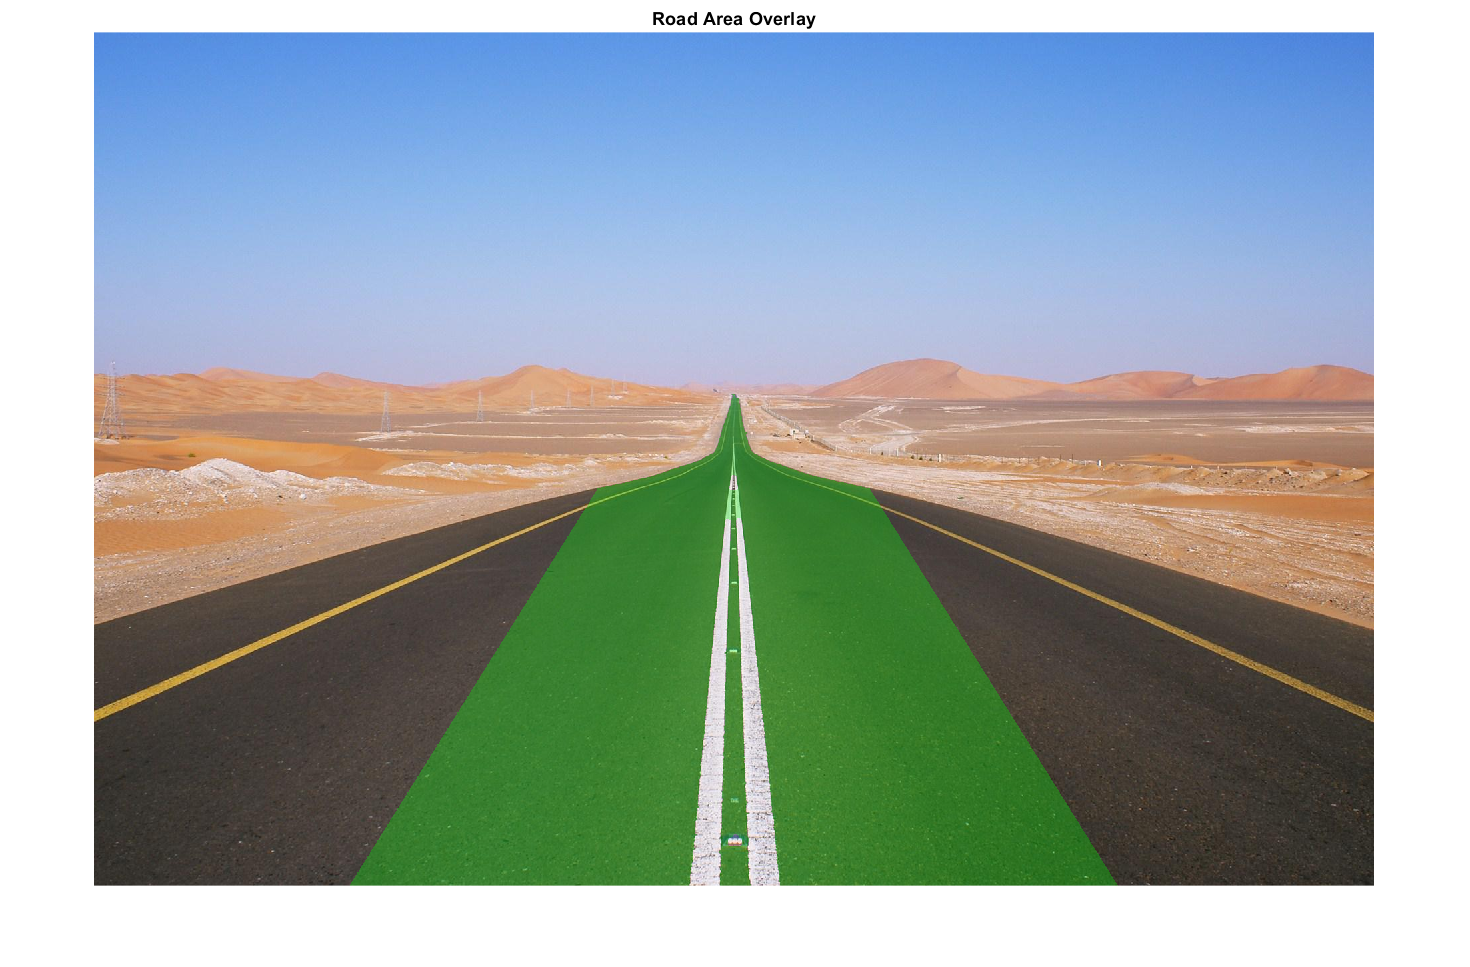

% Robust Desert Road Detection - Focus on strong contrast and lane markings
% Load the image
image = imread('R.jpeg');

% Display original
figure;
subplot(3, 2, 1);
imshow(image);
title('Original Image');

% 1. Convert to grayscale
gray_image = rgb2gray(image);

% 2. Create a region of interest to focus only on the road area
% For this specific road image, we know the road is in the center
[height, width] = size(gray_image);
roi_mask = false(height, width);

% Create a narrower trapezoid focused directly on the road
x_top_left = width * 0.45;      % Narrow at horizon
x_top_right = width * 0.55;
x_bottom_left = width * 0.2;    % Wider at bottom
x_bottom_right = width * 0.8;
y_top = height * 0.4;           % Horizon line
y_bottom = height;              % Bottom of image

roi_vertices = [x_bottom_left, y_bottom; 
                x_top_left, y_top; 
                x_top_right, y_top; 
                x_bottom_right, y_bottom];
                
roi_mask = poly2mask(roi_vertices(:,1), roi_vertices(:,2), height, width);

% 3. Apply strong contrast enhancement to the grayscale image
enhanced = imadjust(gray_image, [0.3 0.7], [0 1]);

% 4. Gaussian smoothing (light smoothing to preserve edges)
smoothed = imgaussfilt(enhanced, 1.0);

% Apply the ROI mask
masked_image = smoothed .* uint8(roi_mask);

subplot(3, 2, 2);
imshow(masked_image);
title('ROI Applied');

% 5. Detect edges using Canny (better at detecting continuous edges)
edges = edge(masked_image, 'canny', [0.1 0.3]);

% Clean up edges
se = strel('disk', 1);
edges = imclose(edges, se);
edges = bwareaopen(edges, 30); % Remove tiny artifacts

subplot(3, 2, 3);
imshow(edges);
title('Edge Detection');

% 6. Use Hough transform to detect lines
[H, theta, rho] = hough(edges);
P = houghpeaks(H, 10, 'threshold', ceil(0.3*max(H(:))));
lines = houghlines(edges, theta, rho, P, 'FillGap', 40, 'MinLength', 30);

% 7. Plot all detected lines first to debug
subplot(3, 2, 4);
imshow(image);
hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'g-', 'LineWidth', 2);
    % Display the angle for debugging
    midpoint_x = mean(xy(:,1));
    midpoint_y = mean(xy(:,2));
    text(midpoint_x, midpoint_y, num2str(lines(k).theta), 'Color', 'yellow');
end
title('All Detected Lines');
hold off;

% 8. Filter lines based on position and angle
% For this specific road, we know:
% - Left boundary lines have negative angles around -45 degrees
% - Right boundary lines have positive angles around 45 degrees
% - The center line has an angle close to 90 degrees (vertical)
center_x = width / 2;

left_lines = [];
right_lines = [];
center_lines = [];

for k = 1:length(lines)
    angle = lines(k).theta;
    midpoint_x = mean([lines(k).point1(1), lines(k).point2(1)]);
    
    % Left boundary conditions
    if midpoint_x < center_x && angle > -65 && angle < -25
        left_lines = [left_lines; lines(k)];
    % Right boundary conditions
    elseif midpoint_x > center_x && angle > 25 && angle < 65
        right_lines = [right_lines; lines(k)];
    % Center line conditions (looking for the white dashed lines)
    elseif abs(midpoint_x - center_x) < width*0.1 && abs(angle) > 80
        center_lines = [center_lines; lines(k)];
    end
end

% 9. Select the best lines by length or position
% If we have multiple candidates, choose the strongest ones
left_line = [];
right_line = [];
center_line = [];

% For left boundary
if ~isempty(left_lines)
    % Find line with angle closest to -45 degrees
    [~, idx] = min(abs([left_lines.theta] - (-45)));
    left_line = left_lines(idx);
end

% For right boundary
if ~isempty(right_lines)
    % Find line with angle closest to 45 degrees
    [~, idx] = min(abs([right_lines.theta] - 45));
    right_line = right_lines(idx);
end

% For center line
if ~isempty(center_lines)
    % Find line with angle closest to 90 degrees (vertical)
    [~, idx] = min(abs(abs([center_lines.theta]) - 90));
    center_line = center_lines(idx);
end

% 10. Visualize filtered lines
subplot(3, 2, 5);
imshow(image);
hold on;

% Draw ROI boundaries for reference
roi_poly = [roi_vertices; roi_vertices(1,:)];
plot(roi_poly(:,1), roi_poly(:,2), 'y-', 'LineWidth', 1);

% Draw the best lines
line_colors = {'r', 'g', 'b'};
line_types = {'Left', 'Right', 'Center'};
has_line = false(1,3);

% Left boundary
if ~isempty(left_line)
    has_line(1) = true;
    xy = [left_line.point1; left_line.point2];
    % Extend line to full ROI height
    slope = (xy(2,2) - xy(1,2)) / (xy(2,1) - xy(1,1) + eps); % Add eps to avoid division by zero
    intercept = xy(1,2) - slope * xy(1,1);
    
    y_top = y_top;
    y_bottom = height;
    x_top = (y_top - intercept) / (slope + eps);
    x_bottom = (y_bottom - intercept) / (slope + eps);
    
    plot([x_top; x_bottom], [y_top; y_bottom], 'r-', 'LineWidth', 3);
end

% Right boundary
if ~isempty(right_line)
    has_line(2) = true;
    xy = [right_line.point1; right_line.point2];
    % Extend line to full ROI height
    slope = (xy(2,2) - xy(1,2)) / (xy(2,1) - xy(1,1) + eps);
    intercept = xy(1,2) - slope * xy(1,1);
    
    y_top = y_top;
    y_bottom = height;
    x_top = (y_top - intercept) / (slope + eps);
    x_bottom = (y_bottom - intercept) / (slope + eps);
    
    plot([x_top; x_bottom], [y_top; y_bottom], 'g-', 'LineWidth', 3);
end

% Center line
if ~isempty(center_line)
    has_line(3) = true;
    xy = [center_line.point1; center_line.point2];
    % Extend line to full ROI height
    slope = (xy(2,2) - xy(1,2)) / (xy(2,1) - xy(1,1) + eps);
    intercept = xy(1,2) - slope * xy(1,1);
    
    y_top = y_top;
    y_bottom = height;
    x_top = (y_top - intercept) / (slope + eps);
    x_bottom = (y_bottom - intercept) / (slope + eps);
    
    plot([x_top; x_bottom], [y_top; y_bottom], 'b-', 'LineWidth', 3);
end

% Add legend showing which lines were detected
detected = line_types(has_line);
detected_colors = line_colors(has_line);
if ~isempty(detected)
    legend(detected, 'Location', 'SouthEast');
end

title('Detected Road Boundaries');
hold off;

% 11. If we couldn't detect natural boundaries, use alternative approach
if ~has_line(1) || ~has_line(2)
    % Let's try detecting the road by its color difference
    subplot(3, 2, 6);
    imshow(image);
    hold on;
    
    % Simple approach: convert to HSV and threshold the V channel
    hsv = rgb2hsv(image);
    v_channel = hsv(:,:,3);
    
    % Apply ROI
    v_masked = v_channel .* double(roi_mask);
    
    % Threshold to separate dark road from light sand
    road_mask = v_masked < 0.5 & v_masked > 0;
    
    % Clean up the mask
    road_mask = bwareaopen(road_mask, 1000);
    se = strel('disk', 5);
    road_mask = imclose(road_mask, se);
    
    % Draw the road mask boundary
    boundaries = bwboundaries(road_mask);
    if ~isempty(boundaries)
        for k = 1:length(boundaries)
            boundary = boundaries{k};
            plot(boundary(:,2), boundary(:,1), 'm-', 'LineWidth', 2);
        end
    end
    
    title('Alternative Road Detection');
    hold off;
    
    % Create additional visualization showing the road mask
    figure;
    imshow(image);
    hold on;
    
    % Show road mask as overlay
    h = imshow(cat(3, zeros(size(road_mask)), ones(size(road_mask)), zeros(size(road_mask))));
    set(h, 'AlphaData', road_mask * 0.3);
    
    title('Road Area Overlay');
    hold off;
end